## **Part B: Extracting, and removing trends**

You don't have to look hard to find periodicity/cycles within datasets that describe environmental processes. Often, understanding the nature of this can help us understand the processes and forcings. There are many different ways in which we can assess this, but in this section we will use the fast fourier transform, and wavelet transform. To run this, we need a data input which **does not contain **`NaN`**, and has equal time intervals between samples**. For this we are going to use the tidal dataset that we used in Block 02. For ease, the tests for equal intervals and interpolation have already been undertaken on the data file that we are going to use.

Therefore we use the interpolated data `[interp_y]:`

% Load in the checked and QC'd dataset

folderIn = 'C:\_git_local\GEO8026_22_23\Block 04\data\' % define as appropriate

folderIn = 'C:\_git_local\GEO8026_22_23\Block 04\data\'


E = readtable([folderIn 'h915a_QA.csv']); 

time_good = E{:,1};
interp_y = E{:,2};

% Apply fft for periodogram
Y = fft(interp_y);
N = length(Y);
Y(1) = [];
power = abs(Y(1:N/2)).^2;

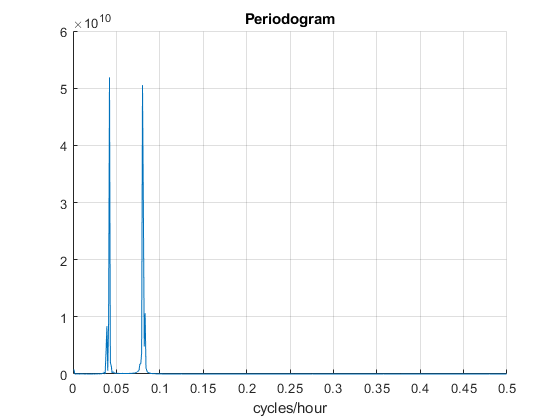

nyquist = 1/2;
freq = (1:N/2)/(N/2)*nyquist;

figure(); hold on;
plot(freq,power), grid on
xlabel('cycles/hour')
title('Periodogram')

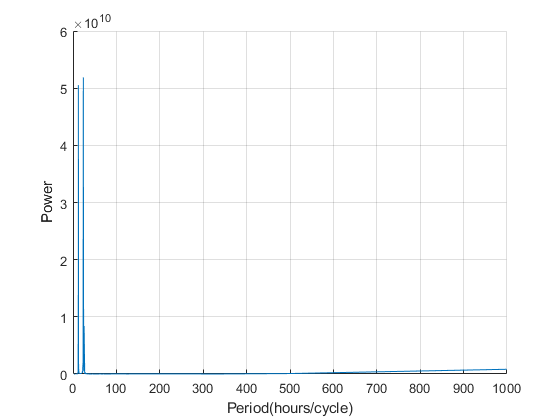


% Spectrogram
figure(); hold on;
period = 1./freq;
plot(period,power), grid on
ylabel('Power')
xlabel('Period(hours/cycle)')

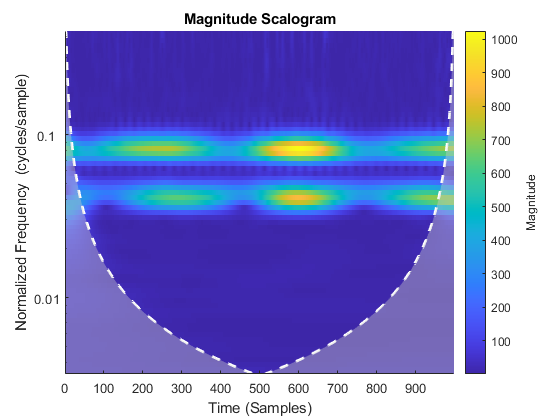


% Continuous 1-D wavelet transform
% Magnitude scalogram
figure(); hold on;
cwt(interp_y);

## Smoothing data (low-pass filter)

Now that we know that the periodicity of the signal is ~12 hours and 24 hours, we can smooth the data over these period. If we wanted to remove the signal of low and high tide we would then analyse this smoothed signal.

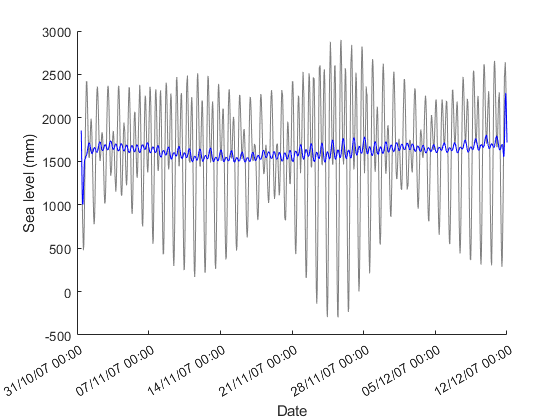


% Apply a smooth of the data with a period of 24 hours
smoothed = smooth(interp_y,24);

figure(); hold on;
% Plot the original data
plot(time_good,interp_y,... % plot the measurements against time
    'Color', [0.5 0.5 0.5],... % set color as gray
    'LineStyle','-'); hold on; % solid line
% Plot the original data
plot(time_good,smoothed,... % plot the measurements against time
    'Color', 'b',... % set color as blue
    'LineStyle','-'); hold on; % solid line

datetick('x','dd/mm/yy HH:MM', 'keepticks'); % set x-axis as date format
ylabel('Sea level (mm)'); % set y-axis label
xlabel('Date'); % set x-axis label

## Management of 'big data'

Some environmental monitoring datasets may pose greater challenges than others when it comes to extracting the information that you want. One particularly challenging example is the daily climate data from NOAA ([https://www.ncei.noaa.gov/products/land-based-station/global-historical-climatology-network-daily](https://www.ncei.noaa.gov/products/land-based-station/global-historical-climatology-network-daily)). This datset contains more than 100,000 stations from across 180 countries, all of which record numerous measurements of the land surface conditions. We are going to use this example to illustrate how we can manage to extract data from the 'big data' archives and analyse the records that we obtain.

Before doing anything, read through the MATLAB .m file called` extracting_noaa.m.`

We can now call the `extarcting_noaa` function. You can use breakpoints and step through the code one line at a time to understand what each line does.

[dtNum,TAVG] = extracting_noaa(folderIn);

Now that we have brought in the datasets, `TAVG` is the daily temperature, and `dtNum` is the corresponding datetime (in numeric format). **Try to use the methods outlined above to extract statistics from this dataset.**

## Summarising change

Let's consider that we are interested in seeing how the temperature varies on an annual basis. This may be useful if we are trying to identify drivers of change on an annual basis. We can extract the summary statistics from the data and plot them too:

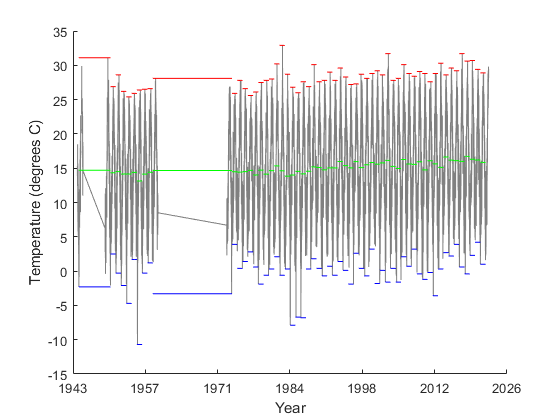

% Let's plot the original data first
figure(); hold on;
plot(dtNum,TAVG,'-',... % solid line
    'Color', [0.5 0.5 0.5]) % color as gray
datetick('x','yyyy', 'keepticks'); % set x-axis as date format
ylabel('Temperature (degrees C)'); % set y-axis label
xlabel('Year'); % set x-axis label

% Lets find the index for the start of each month
dtVec           = datevec(dtNum); % Easiest way is to convert the date to vector format
temp1           = diff(dtVec(:,1)); % find when there is a change in column 1 (i.e. year)
mm_start_idx    = find(temp1 == 1) + 1; % we need to add one to the results as diff finds the cell before the change
mm_end_idx      = find(temp1 == 1);
mm_end_idx      = mm_end_idx(2:end); % we have the index of the end

for a = 1:length(mm_end_idx)
    x_axis              = dtNum(mm_start_idx(a):mm_end_idx(a));
    mm_temp_mean(a)     = nanmean(TAVG(mm_start_idx(a):mm_end_idx(a))); % extract the mean of each year
    mm_temp_std(a)      = nanstd(TAVG(mm_start_idx(a):mm_end_idx(a))); % extract the standard deviation of each year
    mm_temp_min(a)      = nanmin(TAVG(mm_start_idx(a):mm_end_idx(a))); % extract the minimum value of each year
    mm_temp_max(a)      = nanmax(TAVG(mm_start_idx(a):mm_end_idx(a))); % extract the maximum value of each year

    
    % Lets overlay some of this information on the plot
    % Let's start with the mean temperature for each year
    y_axis              = repmat(mm_temp_mean(a),length(x_axis),1); % repmat duplicates the value presented. In this case it duplicates it so it is the same length as the x_axis data
    plot(x_axis, y_axis,...
        'Color', 'g');
    hold on; % color as dark red
    
    % Now plot the min
    y_axis              = repmat(mm_temp_min(a),length(x_axis),1);
    plot(x_axis, y_axis,...
        'Color', 'b');
    hold on; % color as blue
    
    % and the maximum
    y_axis              = repmat(mm_temp_max(a),length(x_axis),1);
    plot(x_axis, y_axis,...
        'Color', 'r');
    hold on; % color as blue
   
end

## Detrending data (high-pass filter)

Some datasets may exhibit a long-term trend. Land surface temperature data acquired over the 20th Century is one such example. We can remove trends from timeseries data using the detrend command. However. the standard detrend command in MATLAB does not allow `NaN` data. We would therefore have had to interpolate missing data to run this function. Because of this, we we are going to use a modified version of it which does and is fit for our purpose:

% Detrending data
figure(); hold on;
y = detrend_nan(TAVG); 
plot(dtNum,TAVG,dtNum,y,dtNum,TAVG-y,':k')
datetick('x','yyyy', 'keepticks'); % set x-axis as year format
ylabel('Temperature (degrees C)'); % set y-axis label
xlabel('Year'); % set x-axis label

From this example, we can see that the trend is gently increasing over time. When we apply the detrend, this linear increase is removed and it is rebased with a mean of zero. Having a base of zero is not necessarily the most intuitive therefore we can convert back to actual degrees with the trend removed:

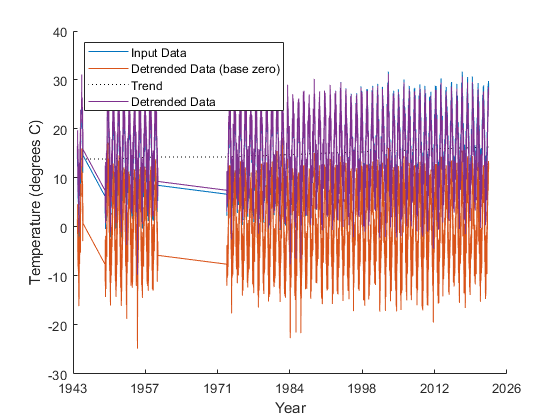

% Detrending data
T_mean = nanmean(TAVG);
T_adj  = y  + T_mean;
plot(dtNum,T_adj);
legend('Input Data','Detrended Data (base zero)','Trend', 'Detrended Data', 'Location','northwest') 